# **LAB8_forceyArduino**

------------------------------------------------------------------------------------------------------------------------------------------------------

Created: 16 May 2019

By: Samuel Bechara and Joshua Christopher

## Introduction

You know when you are doing self-checkout at the grocery store and the annoying little machine keeps insisting you need to put the pumpkin in the bagging area EVEN THOUGH YOU ALREADY DID WHAT IS WRONG WITH THIS PIECE OF JUNK MACHINE?!? 

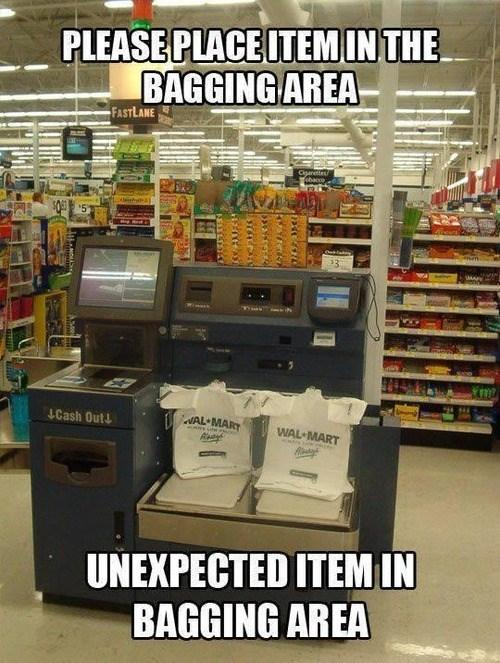

Well you can blame the force sensor for that. In this lab we are going to learn about force sensors so hopefully one day you can go work for whoever makes those self checkout machines and save humanity from this madness. Force sensors are used for all sorts of weight-measuring applications, such as for sorting single-stream recycling to making sure an elevator isn't overloaded. Museums use force sensors to detect changes in weight on their display items to see if someone is stealing them. 

A non-weight application is using force sensors in those punching bag games in bars. They have a force sensor at the top that the bag slams in to when you punch it. Similarily, crash test dummys use sensors to detect how much force various body parts get hit with.

In this lab, we are going to learn how to use force sensors with Arduinos. This will reinforce the programming concepts you learned in class the last week: relational and logical operators will be used in conjunction with decision statements to create a useful force sensor. Recall that relational opreators test to see if something is true or false by comparing two values, for example:

weight = 5.2; % pounds
threshold = 5.0; % pounds
weight > threshold

will return true if the weight variable is larger than our threshold variable. Logical operators can be used to string together a series of relational operators, for example to check that multiple conditions are true:

lower_threshold = 4.0; % pounds
upper_threshold = 6.0; % pounds
(weight > lower_threshold) & (weight < upper_threshold)

will check that the variable weight is between an upper threshold and a lower threshold. MATLAB's decision statements are then used to take some action if the conditions evaluate to true.

if weight > threshold
    disp("Weight is above threshold!")
end

Here we display a message if the weight is above the threshold, but we could just as easily turn on the Arduino's light on digital pin 13 if we wanted. 

There will be two phases to this lab:

- First we will set up the force sensor by itself and write some code to test that it is working.

- Second we are going to add some LEDs that we will turn on or off depending on how much force we are detecting.

Note how we will start with a simple setup and make sure that is working before we add additional complexity. This is something you should always do when working on projects: start small and simple, test, then slowly add functionality and test the new functionality.

## Section 1: Use the Force

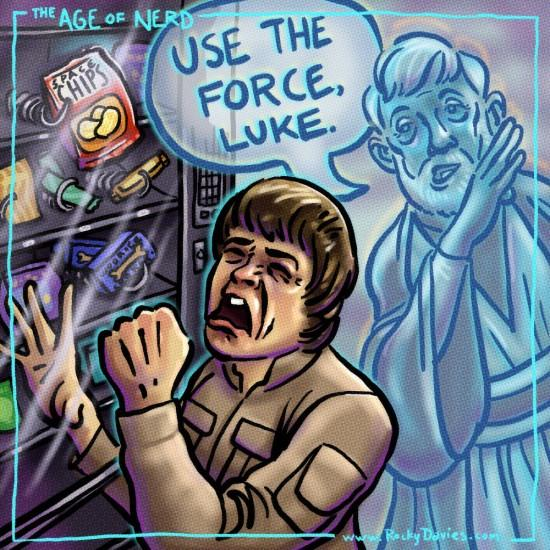

Unfortunately not that kind of force. We are going to hook up the force sensor and have it display force values to the Matlab Command Window. Like last week, there is a hardware setup step and a software step. Lets dive right in.

### Part A: Hardware Setup

For this lab we will be using the force sensor. It has a striped side which is the front, and a plain black side which is the back. Before we can integrate this component with a breadboard, we will need to modify it a bit. First, lets take a look at the force sensor and clinch connector that we will use:

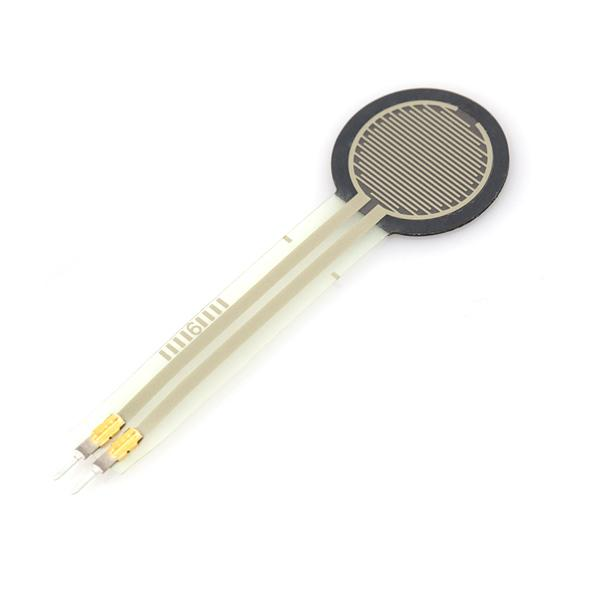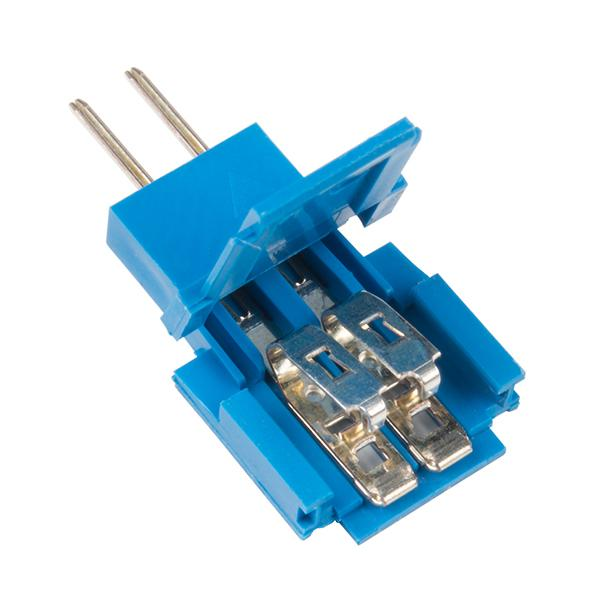

The force sensor has a round head and actually works by changing its resistance as a load is applied. You can find more information about the force sensitive resistor (FSR) here: [https://www.sparkfun.com/products/9375.](https://www.sparkfun.com/products/9375.) The sensors have solder tabs that are stapled through a flexible substrate to make contact with the semi-conductive material. Some assembly required. 

What we are going to do is cut off the ends of the sensor and use the clinch connector to make a nice connection.

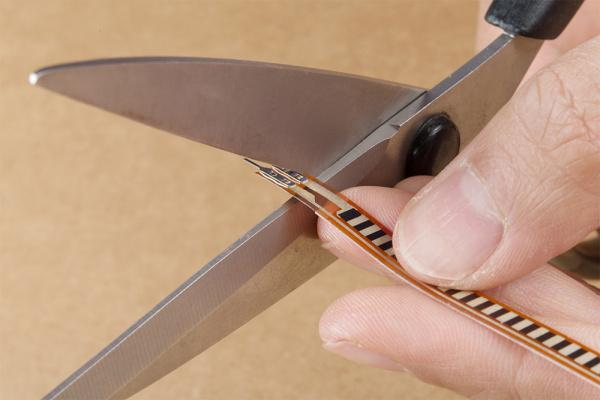

The first step is to cut off the ends...scary! Next grab your clinch connector:

Stick your force sensor into the clinch so that the silver stripes line up with the metal clinchy parts:

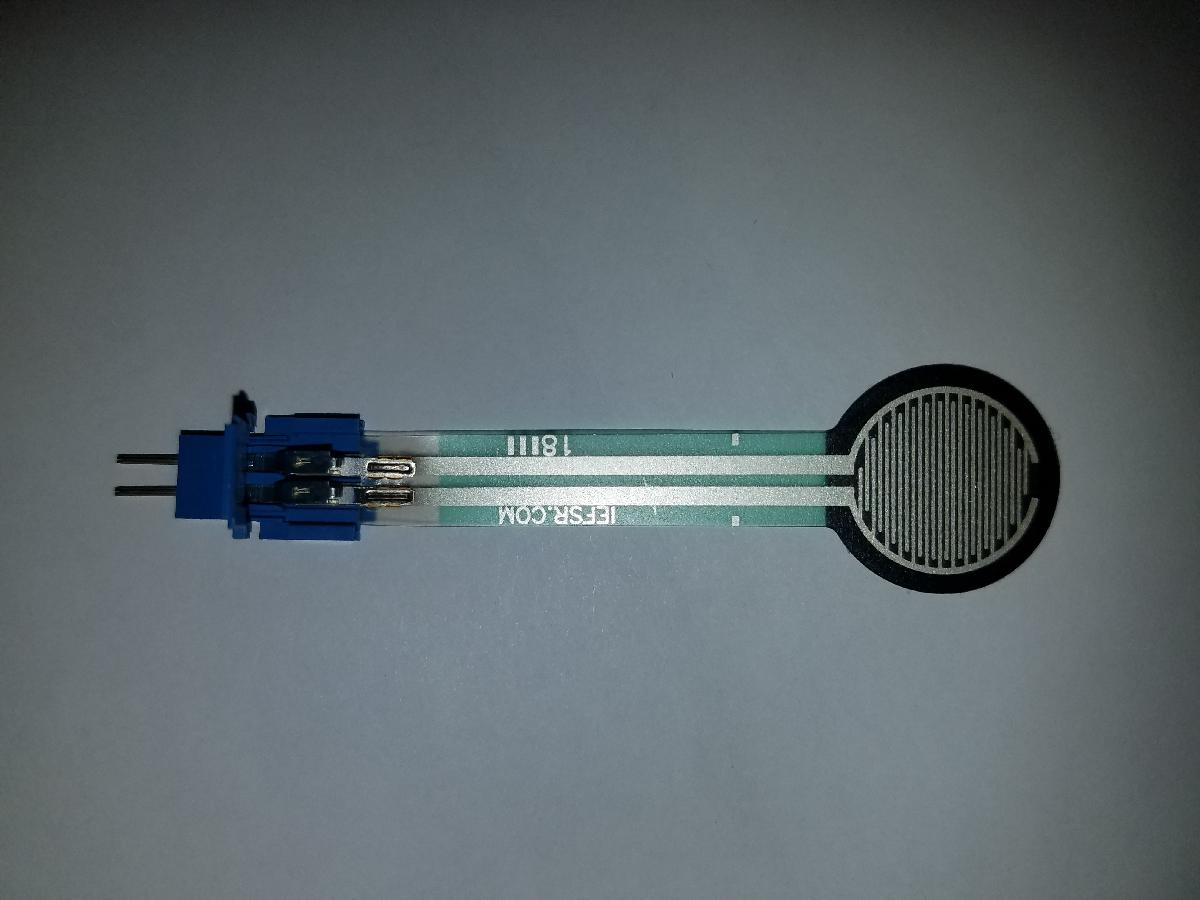

Next, use pliers to squeeze down the clinch. Make sure that it snaps all the way shut and the force sensor can't winggle around inside the clincher.

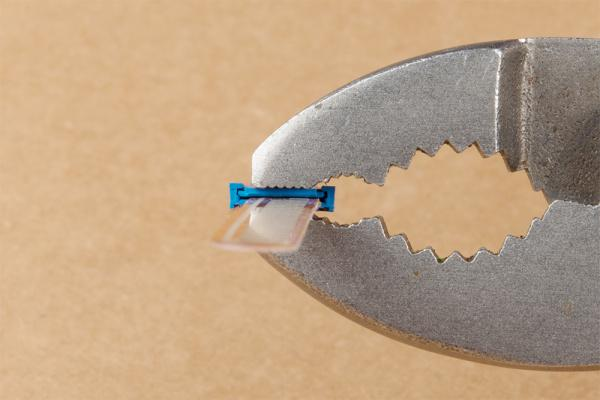

Tadaa! Here is our clinched up force sensor.

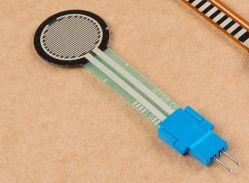

Now we can connect our force sensor to our breadboard! Take a look at the diagram below. Notice that when you are looking at the striped side of the force sensor, the positive lead is on the right side and the negative lead is on the left side. The diagramming software we are using doesn't show the clinch so just pretend it is there.

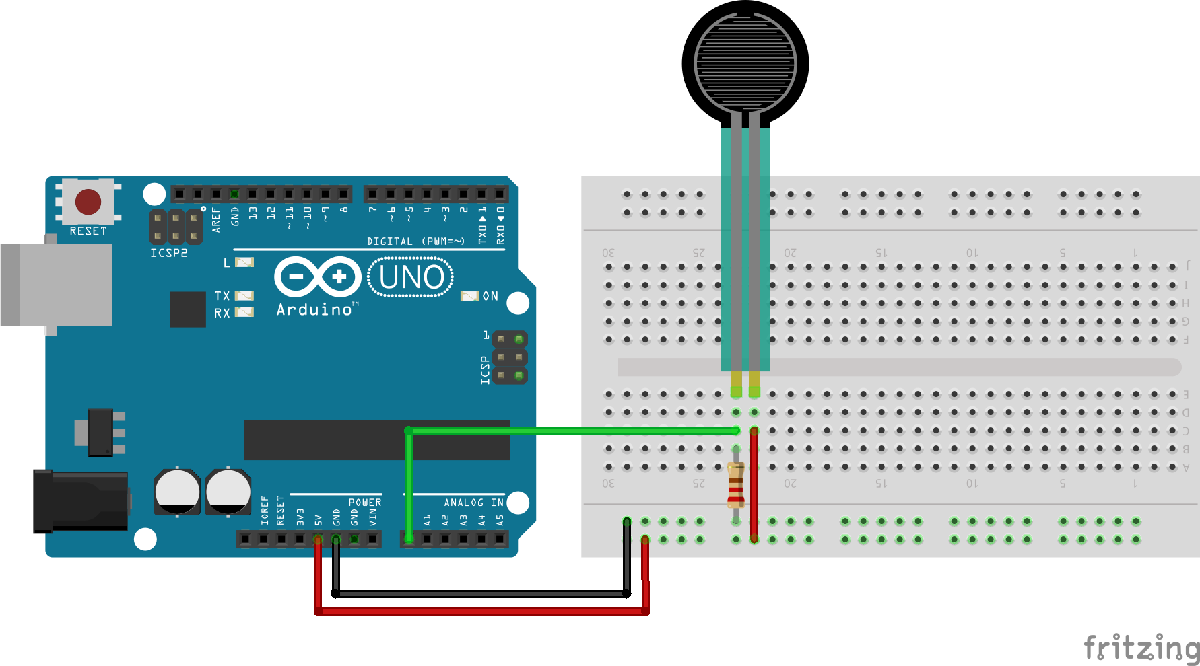

The positive side of the force sensor is connected to the 5v power port on the Arduino. The negative side splits off into two different directions. The green line goes to the A0 Analog In port. Also connected to the negative side is a resistor which leads to ground. Once you have everything connected, its time to move on to the software.

### Part B: Software

From here on out I am going to shorten the force sensor to FSR, which stands for Force Sensitive Resistor. Surprisingly, we don't need to learn any new Matlab-Arduino specific functions! The output from the FSR is connected to the A0 analog in pin which means that we need to read voltage from that pin. This is just like last week when we read voltage from the output of the temperature sensor. 

In order to get accurate readings from the force sensor, we need to take to "calibrate" the force sensor based on the supplied voltage and the resistance of the resistor we added to the circuit. If you have a multimeter available, grab that and measure the actual voltage output of the 5V power port on the Arduino. Next, measure the resistance across the resistor. They should probably be within 10% of the nominal value. If you don't have a multimeter on hand, just use the nominal value.

Next we need to convert the voltage reading from the FSR into something we can work with, namely the force (or mass? The spec sheet says Force with unit grams?!?). First we need to compute the resistance across the FSR, given by this handy equation in the spec sheet:


$$V_{out} = \frac{R_MV_{+}}{R_M+R_{FSR}}$$


We know $V_{out}$ from reading the voltage, and $V_{+}$ from the voltage supplied by the Arduinio. The resistor that we choose is the value for $R_M$, so we need to solve for $R_{FSR}$. Once we know that, we need to compute the conductance, which is just $G =1/R_{FSR}$, the inverse of the resistance of the FSR.

Lastly we convert from conductance to force using the equation:


$$F = \begin{cases}\left(G - 7.5\mathrm{E}{-4}) / 3.2639\mathrm{E}{-7} & \textrm{for}~R_{FSR} \leq 600 \\ G / 6.42857\mathrm{E}{-7} & \textrm{otherwise} \end{cases}$$


That is, if the resistance from the FSR is less than or equal to 600, compute the force using the top line. For all other resistances, use the bottom line.

What happens if we measure no voltage from the FSR? Well then we don't use the force calculations and can just report the force as zero. I really recommend sketching this process as a flowchart on a piece of paper before you try to implement this.

clear;

FSR_PIN = 'A0'; % Pin that our FSR is connected to
% If we want to get accurate values we need to measure these things
VCC = ; % Measured voltage of Ardunio 5V line
R_DIV = ; % Measured resistance of the resistor. Check the size of your resistor!

forceArduino = ;% Connect to your arduino here!
waitTime = 2; % How long we want to wait between readings

% This while statement tells the Arduino we want to run
% all the code inside it forever (or until we press the
% stop button)
while(1)
    fsrVoltage = ; % read in the voltage from the FSR
    
    % If the reading from FSR is non-zero, we need to compute the force as
    % follows. Follow the specific instructions and write your code immediately below
    % each instruction
    % 1. If the FSR voltage is non-zero (write the appropriate if statement below)
    
            %1.1 Compute the resistance and store the value in a variable
            %    called fsrResistance
            
            
            fprintf("Reistance is %f\n",fsrResistance); % print out the resistance
            %1.2 Compute the conductance and store the value in a variable
            %    called fsrConductance
            
            
            %1.3. If the resistance computed above is less than or equal to
            %     600, use the first equation to calculate the force 
            %     (see piecewise equation given in the problem statement.)
            
            
            
            %1.4. Otherwise, use the second equation to calculate the force.
            
            
            
            
            fprintf("\tThe force is %f\n",force); % print out the force 
            pause(waitTime); % don't measure voltage a million times a second     
        
     %2. If the FSR voltge is zero (i.e. if we don't measure voltage), don't compute force (but maybe
     %   still do some stuff like say we found no voltage, or pause)
     else %if FSR voltage is zero
            fprintf("No resistance detected\n");
            pause(waitTime);
     end %end of if statement ( it is supposed to be included above by you)
            
end %end of while loop
%Note: Remember to include end for your if statements
%      Add equations and additional if statements as desired.

Fill out the code above so that it can run properly. Then test out your force sensor! Run the code and watch the output in the Command Window. Give the FSR a squeeze with your fingers. Do you see the force increasing as you squeeze it harder? What is the lightest you can squeeze it and still get a reading? What happens if you change the values of R_DIV and VCC? Does that make your sensor more or less sensitive?

Get an intuitive feel for how much force you are applying compared to the force displayed on the Command Window. Note what output values are typical, you are going to need it for the next section. Lastly, find some object of medium weight. Maybe your cell phone or something a little heavier. Put that onto the FSR and note how much force is applied. We're going to call this object your Reference Object and the force applied the Reference Force.

## Section 2: More blinky lights!

Now that you have a working force sensor, lets add something fun to it! 

### Part A: Hardware setup

Grab 5 LEDs, 5 resistors, and 10 wires. Attach the positive side of the LEDs to digital pins, and the negative side of the LEDs to ground. Make sure you stick resistors in the line somewhere, it doesn't matter if they are on the positive or negative side. I stuck them on the negative side as shown in the diagram below.

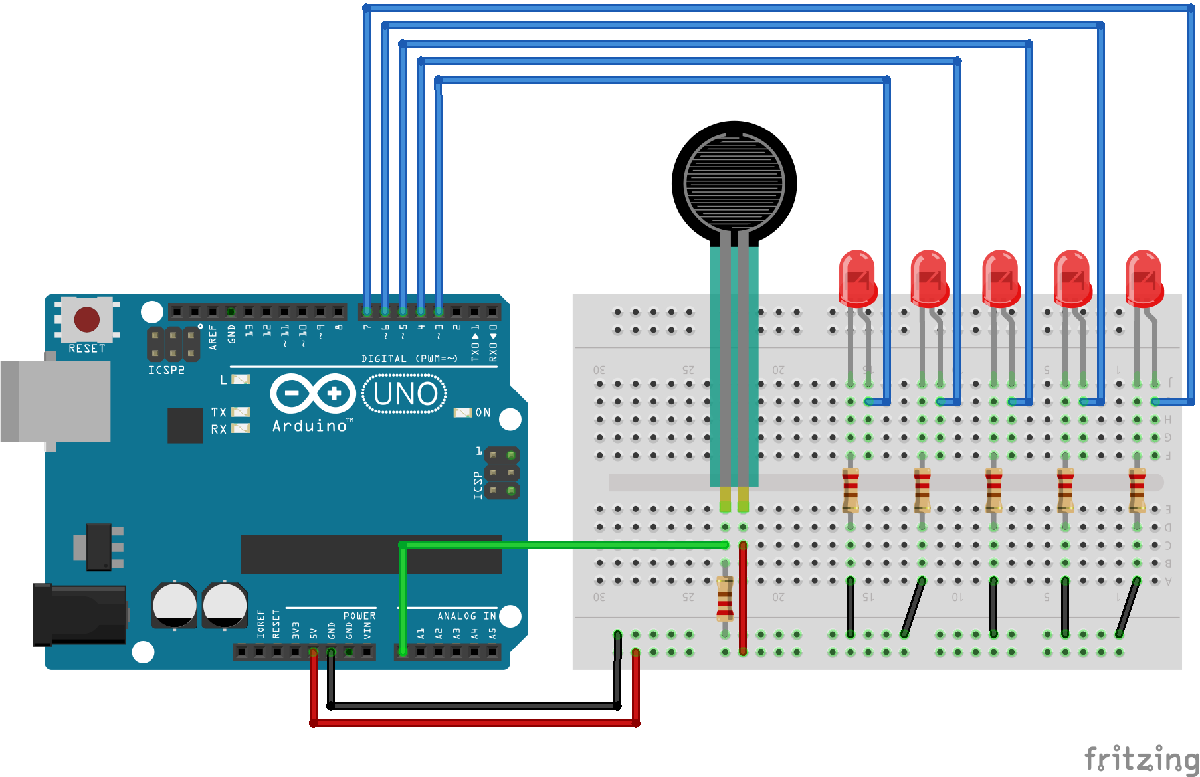

I'm going to leave it up to you to hook this up without further step by step instructions.

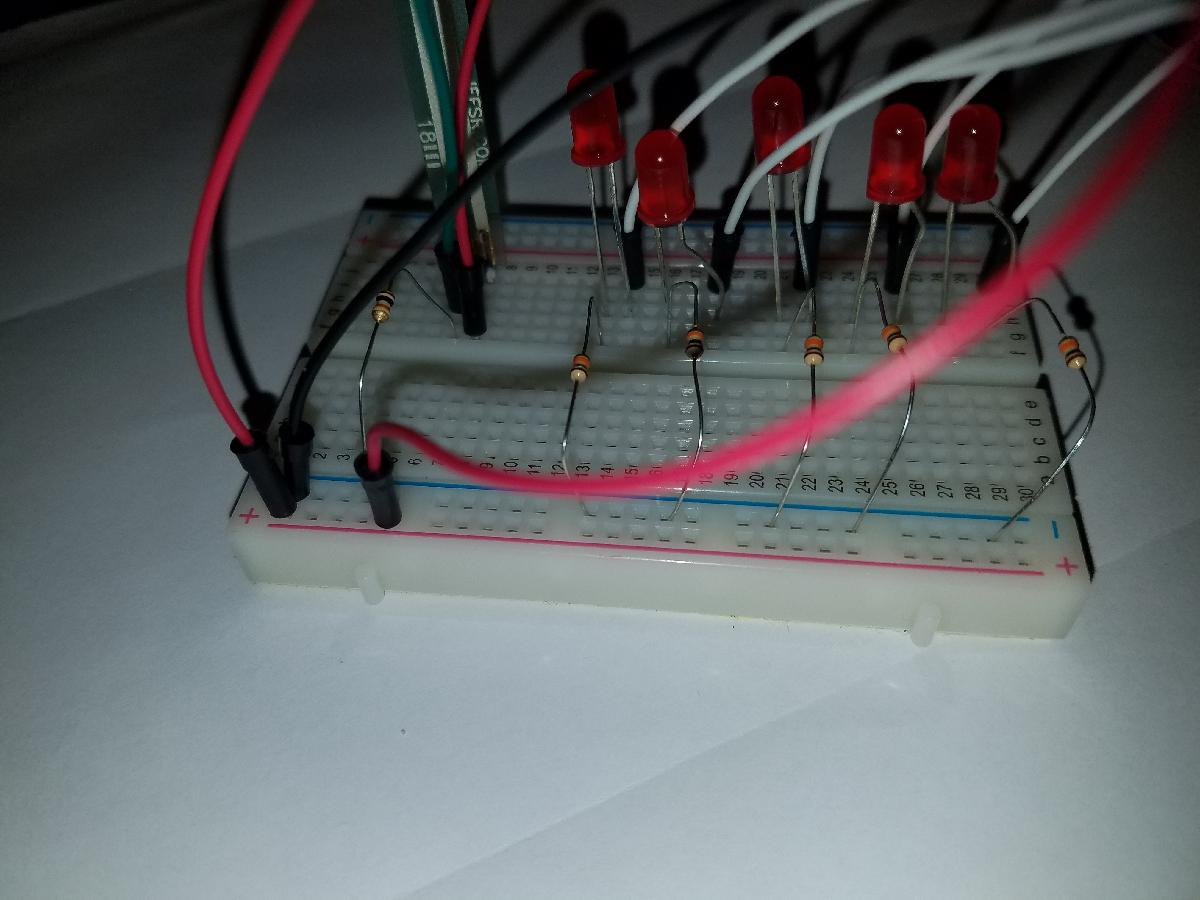

Here is a picture of my breadboard. Notice I got "lazy" by connecting the resistors directly to the breadboard's ground. You can take little shortcuts like this as long as your circuit is *electrically equivalent*. Since wires are considered no resistance (and no capacitance etc.) you can usually eliminate them with no effect. 

### Part B: Software

We already know how to turn on LEDs from previous labs: we just need to figure out what digital pin the LED is connected to then set the value of that pin to 1! So lets turn on some number of the LEDs based on how much force is being applied. We are going to use relational operators and decision statements to determine which LEDs should be turned on and off.

We can reuse the code from above and just stick our LED-logic in:

clear;

FSR_PIN = 'A0'; % Pin that our FSR is connected to
% If we want to get accurate values we need to measure these things
VCC = ; % Measured voltage of Ardunio 5V line
R_DIV = ; % Measured resistance of 3.3k resistor. Check the size of your resistor!

forceArduino = ;% Connect to your arduino here!
waitTime = 2; % How long we want to wait between readings

% This while statement tells the Arduino we want to run
% all the code inside it forever (or until we press the
% stop button)
while(1)
    fsrVoltage = ; % read in the voltage from the FSR
    
    % If the reading from FSR is non-zero, we need to compute the force as
    % follows. Follow the specific instructions and write your code immediately below
    % each instruction.
    % 1. If the FSR voltage is non-zero (write the appropriate if statement below)
    
            %1.1 Compute the resistance and store the value in a variable
            %    called fsrResistance
            
            
            fprintf("Reistance is %f\n",fsrResistance); % print out the resistance
            %1.2 Compute the conductance and store the value in a variable
            %    called fsrConductance
            
            
            %1.3. If the resistance computed above is less than or equal to
            %     600, use the first equation to calculate the force 
            %     (see piecewise equation given in the problem statement.)
            
            
            
            %1.4. Otherwise, use the second equation to calculate the force.
            
            
            
            
            fprintf("\tThe force is %f\n",force); % print out the force 
            writeDigitalPin(forceArduino, 'D07', 1); %LED on
            writeDigitalPin(forceArduino, 'D06', 0); %LED off
            writeDigitalPin(forceArduino, 'D05', 0); %LED off
            writeDigitalPin(forceArduino, 'D04', 0); %LED off
            writeDigitalPin(forceArduino, 'D03', 0); %LED off
            %1.5. Turn on LEDs that correspond with how much weight we are applying
            %     based on the following criteria:
            %     If force > 2000, turn on LEDs at pins D03, D04, D05, and D06 
            %     If 1000 < force <= 2000, turn on LEDs at pins D04, D05, and D06 
            %     If 500 < force <= 1000, turn on LEDs at pins D05, and D06 
            %     If 250 < force <= 500, turn on LED at pin D06 
           
            
            
            
                        
            pause(waitTime); % don't measure voltage a million times a second     
     %2. If the FSR voltge is zero (i.e. if we don't measure voltage), don't compute force (but maybe
     %   still do some stuff like say we found no voltage, or pause)
     else %if FSR voltage is zero 
            %Write commands below to turn off all LEDs (D03,D04, D05, D06, and D07)
         
            fprintf("No resistance detected\n");
            pause(waitTime);
     end %end of the first if statement (the if statement is supposed to be included above by you)
            
end %end of while loop

%Note: Remember to include end for your if or if-else statements.
%      Add equations and additional if statements as desired.

Using your intuition and the values you noted in the first section, create more conditionals that light up 1, 2, 3, 4, or 5 LEDs based on the force applied. Make it so 3 LEDs light up when you put your reference object on the FSR. Then find rather heavy object, like a textbook. Make sure that all 5 LEDs light up. You might have to adjust the values in your relational operators to make this happen. Make it so that 4 LEDs will light up for something that weighs in between your Reference Object and your heavy object. 

Next find the lightest object that activates your FSR. Repeat the process above but for calibrating your relational operators to the light object turning on 1 LED. Lastly find something that weighs between your Reference Object and your light object that turns on 2 LEDs.

You should now have  a range of forces you can apply to your FSR to activate various numbers of LEDs. Grab a partner and try to find something of equal weight to their reference object, Indiana Jones style:

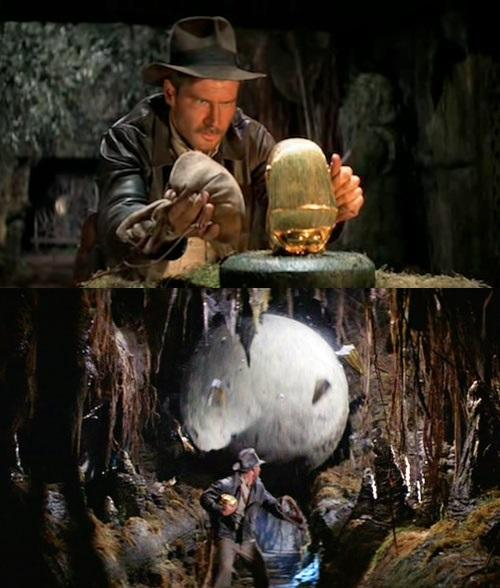

Implementing a rolling boulder is optional.

# Deliverable

Your LA will have a reference weight that they will let you use during this lab, you need to figure out the force applied by that object on your force sensor. If you don't finish at least Section 1 of this lab, then try to find an object that is roughly the same weight. For example, you can try stacking coins on the force sensor. Start by putting just a couple of coins and increase the number of coins gradually, meanwhile observing the change in the output force. Calibrate your relational operators so that 3 LEDs turn on with the reference weight. At the next lab, the LAs will have the reference weight as well as some heavier and lighter weights. You need to complete this lab so that with the heavier weights more LEDs turn on and with the lighter weights less LEDs turn on.